clear
[hand1, dhpar{1}, base{1}] = OWN_human20DOF

base = 1×5 cell array
    {4×4 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


hand1 = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Custom'


dhpar = 1×1 cell array
    {1×5 cell}


base = 1×1 cell array
    {1×5 cell}


base = 1×1 cell array
    {4×4 double}


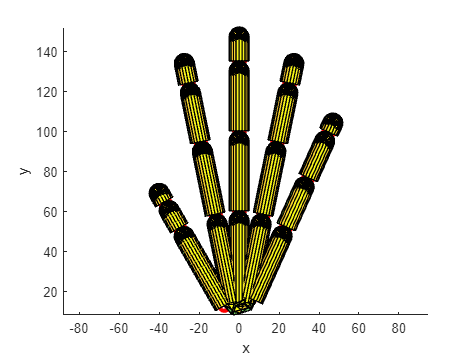

hand2 = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 24
         q: [24×1 double]
       qin: [24×1 double]
      qinf: [24×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [24×24 double]
        cp: []
        Kq: [24×24 double]
        Kz: [24×24 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [24×2 double]
    active: [24×1 double]
      type: 'Hand with 24 DoFs'
      qmin: [24×1 double]
      qmax: [24×1 double]
     Links: {[45 15 10]  [45 37 30 15]  [48 40 35 17]  [45 37 30 15]  [40 27 25 10]}


dhpar = 1×2 cell array
    {1×5 cell}    {1×5 cell}


base = 1×2 cell array
    {1×5 cell}    {1×5 cell}


HandPlot(hand1, 1, [-60,30], [-100,50, 0, 200])

[hand2, dhpar{2}, base{2}] = SGhuman24DoF

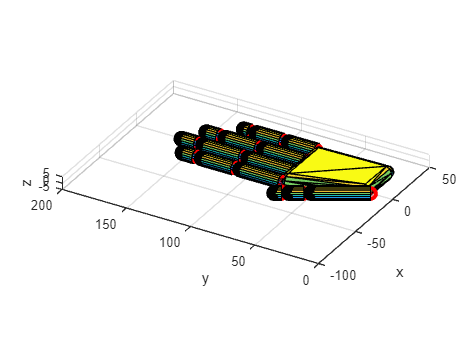

HandPlot(hand2, 1, [-60,30], [-100,50, 0, 200])


[hand3, dhpar{3}, base{3}] = SGparadigmatic

hand3 = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


dhpar = 1×3 cell array
    {1×5 cell}    {1×5 cell}    {1×5 cell}


base = 1×3 cell array
    {1×5 cell}    {1×5 cell}    {1×5 cell}


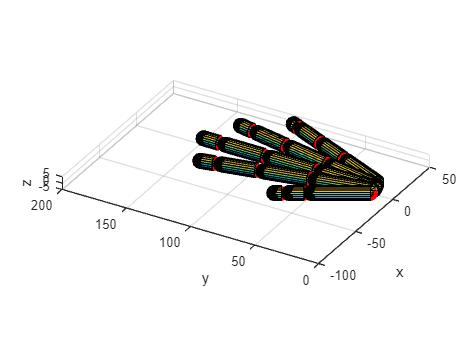

HandPlot(hand3, 1, [-60,30], [-100,50, 0, 200])


dhparP = dhpar{2};
dhparP{2} = dhpar{2}{2}(2:end, :);
dhparP{3} = dhpar{2}{3}(2:end, :);
dhparP{4} = dhpar{2}{4}(2:end, :);
dhparP{5} = dhpar{2}{5}(2:end, :);

[hand4, dhpar{4}, base{4}] = SG_OWN_GenHand(dhparP, base{3})

hand4 = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


dhpar = 1×4 cell array
    {1×5 cell}    {1×5 cell}    {1×5 cell}    {1×5 cell}


base = 1×4 cell array
    {1×5 cell}    {1×5 cell}    {1×5 cell}    {1×5 cell}


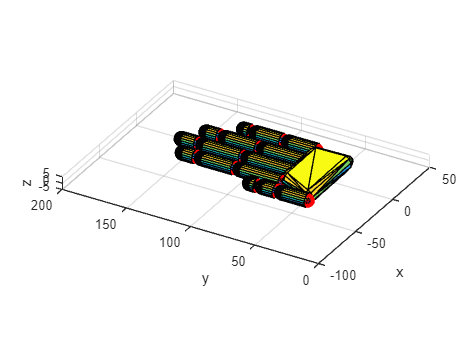

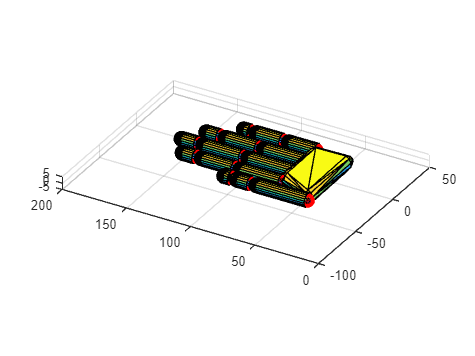

HandPlot(hand4, 1, [-60,30], [-100,50, 0, 200])

display('20dof')

20dof


base{1}{1}

ans =    -0.5000   -0.8660         0   -7.5000
    0.8660   -0.5000         0   12.9904
         0         0    1.0000         0
         0         0         0    1.0000


base{1}{2}

ans =      0    -1     0   -24
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{1}{3}

ans =      0    -1     0    -8
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{1}{4}

ans =      0    -1     0     8
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{1}{5}

ans =      0    -1     0    24
     1     0     0    73
     0     0     1     0
     0     0     0     1


display('24dof')

24dof


base{2}{1}

ans =    -0.5000   -0.8660         0   -7.5000
    0.8660   -0.5000         0   12.9904
         0         0    1.0000         0
         0         0         0    1.0000


base{2}{2}

ans =    -0.2000   -0.0000   -0.9798   -3.0000
    0.9798   -0.0000   -0.2000   14.6969
         0   -1.0000    0.0000         0
         0         0         0    1.0000


base{2}{3}

ans =     0.0000   -0.0000   -1.0000    0.0000
    1.0000    0.0000    0.0000   12.5000
         0   -1.0000    0.0000         0
         0         0         0    1.0000


base{2}{4}

ans =     0.2000   -0.0000   -0.9798    3.0000
    0.9798    0.0000    0.2000   14.6969
         0   -1.0000    0.0000         0
         0         0         0    1.0000


base{2}{5}

ans =     0.4097   -0.0000   -0.9122    7.1695
    0.9122    0.0000    0.4097   15.9640
         0   -1.0000    0.0000         0
         0         0         0    1.0000


display('par')

par


base{3}{1}

ans =      0    -1     0   -37
     1     0     0    45
     0     0     1     0
     0     0     0     1


base{3}{2}

ans =      0    -1     0   -24
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{3}{3}

ans =      0    -1     0    -8
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{3}{4}

ans =      0    -1     0     8
     1     0     0    73
     0     0     1     0
     0     0     0     1


base{3}{5}

ans =      0    -1     0    24
     1     0     0    73
     0     0     1     0
     0     0     0     1



display('20dof')

20dof


dhpar{1}{1}

ans =    -1.5708         0         0         0
         0   45.0000         0         0
    1.5708   15.0000         0         0
         0   10.0000         0         0


dhpar{1}{2}

ans =    -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{1}{3}

ans =    -1.5708         0         0         0
         0   40.0000         0         0
         0   35.0000         0         0
         0   17.0000         0         0


dhpar{1}{4}

ans =    -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{1}{5}

ans =    -1.5708         0         0         0
         0   27.0000         0         0
         0   25.0000         0         0
         0   10.0000         0         0


display('24dof')

24dof


dhpar{2}{1}

ans =    -1.5708         0         0         0
         0   45.0000         0         0
    1.5708   15.0000         0         0
         0   10.0000         0         0


dhpar{2}{2}

ans =     1.5708   45.0000         0         0
   -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{2}{3}

ans =     1.5708   48.0000         0         0
   -1.5708         0         0         0
         0   40.0000         0         0
         0   35.0000         0         0
         0   17.0000         0         0


dhpar{2}{4}

ans =     1.5708   45.0000         0         0
   -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{2}{5}

ans =     1.5708   40.0000         0         0
   -1.5708         0         0         0
         0   27.0000         0         0
         0   25.0000         0         0
         0   10.0000         0         0


display('par')

par


dhpar{3}{1}

ans =    -1.5708         0         0         0
         0   25.0000         0         0
    1.5708   15.0000         0         0
         0   10.0000         0         0


dhpar{3}{2}

ans =    -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{3}{3}

ans =    -1.5708         0         0         0
         0   40.0000         0         0
         0   35.0000         0         0
         0   17.0000         0         0


dhpar{3}{4}

ans =    -1.5708         0         0         0
         0   37.0000         0         0
         0   30.0000         0         0
         0   15.0000         0         0


dhpar{3}{5}

ans =    -1.5708         0         0         0
         0   27.0000         0         0
         0   25.0000         0         0
         0   10.0000         0         0


nb{1} = [   -0.5   -1    0   -15; ...
             0.9    -0.25   0    13; ...
             0       0      1     0; ...
             0       0      0     1]

nb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


nb{2} = base{1}{2}

nb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


nb{3} = base{1}{3}

nb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


nb{4} = base{1}{4}

nb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


nb{5} = base{1}{5}

nb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}



dhp{1} = [   -1.5708         0              0         0; ...
             -0.7804        40.0000         0         0; ...
              1.5708        15.0000         0         0; ...
              0             10.0000         0         0]

dhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}



dhp{2} = dhpar{1}{2}

dhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


dhp{3} = dhpar{1}{3}

dhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


dhp{4} = dhpar{1}{4}

dhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


dhp{5} = dhpar{1}{5}

dhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}



[hand, Ndhp, Nnb] = SG_OWN_GenHand(dhp, nb)

hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


Ndhp = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


Nnb = 1×5 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


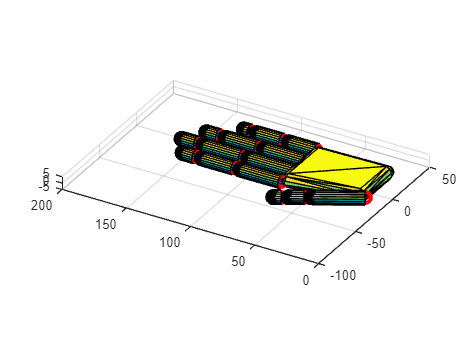

HandPlot(hand, 1, [-60,30], [-100,50, 0, 200])

TP = (0:10:90)';
TP2 = [TP,TP,TP];
TP2 = [zeros(size(TP2,1), 1), TP2];
TP3 = (0:1:9)';
TP(:, 2:4) = zeros(size(TP,1), 3);
r = size(TP,1);
posS = [TP, zeros(r, 16)];
posS(r+1:2*r, :) = [TP(:,[2,1,3,4]), zeros(r, 16)];
posS(2*r+1:3*r, :) = [TP(:,[2,3,1,4]), zeros(r, 16)];
posS(3*r+1:4*r, :) = [TP(:,[2,3,4,1]), zeros(r, 16)];
R = 4*r;
r = size(TP3,1);
TP3(:, 2:4) = zeros(size(TP3,1), 3);
posS(R+1:R+r, :) = [zeros(r, 4), TP3, zeros(r, 12)];
R = R+r;
r = size(TP2,1);
posS(R+1:R+r, :) = [zeros(r, 4), TP2, zeros(r, 12)];

posS2 = posS(:,[1,2,3,4, 9, 5,6,7,8, 9, 9,10,11,12, 9, 13,14,15,16, 9, 17,18,19,20]);
directory = 'anims';
name = "test_N.avi"

name = "test_N.avi"

hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


hand = struct with fields:
         F: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
         n: 5
         m: 20
         q: [20×1 double]
       qin: [20×1 double]
      qinf: [20×1 double]
     ctype: 1
     ftips: [3×5 double]
         S: [20×20 double]
        cp: []
        Kq: [20×20 double]
        Kz: [20×20 double]
         H: []
         J: []
        JS: []
        Wr: [6×1 double]
        Kw: [6×6 double]
     limit: [20×2 double]
    active: [20×1 double]
      type: 'Paradigmatic'


h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 800 800]
       Units: 'pixels'

  Show all properties


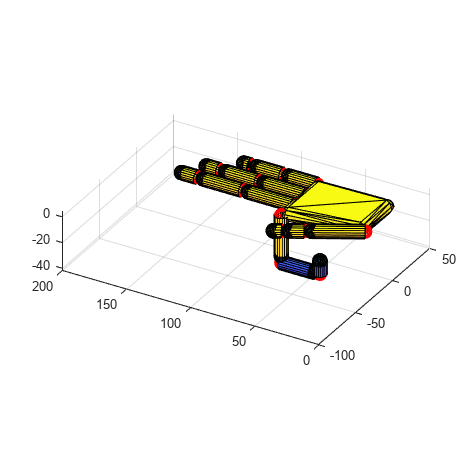

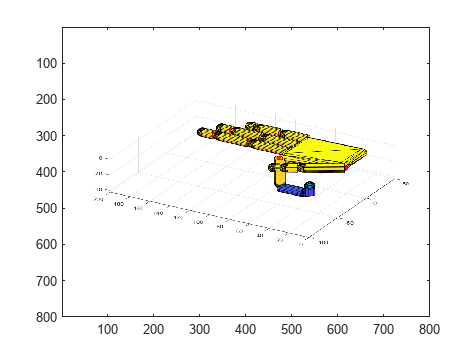

SG_OWN_HandAnim(hand, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name)

stand =  [0,0,0,0,               0,0,0,0,                0,0,0,0,               0,0,0,0,                    0,0,0,0]

stand =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fist =   [0,1,1,1,               0,1,1,1,                0,1,1,1,               0,1,1,1,                    0,1,1,1]

fist =      0     1     1     1     0     1     1     1     0     1     1     1     0     1     1     1     0     1     1     1


spear =  [1,-0.5,-0.5,-0.5,      1,-0.5,-0.5,-0.5,       0,-0.5,-0.5,-0.5,      -1,-0.5,-0.5,-0.5,          -1,-0.5,-0.5,-0.5]

spear =     1.0000   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000         0   -0.5000   -0.5000   -0.5000   -1.0000   -0.5000   -0.5000   -0.5000   -1.0000   -0.5000   -0.5000   -0.5000


spread = [-1,-0.5,-0.5,-0.5,    -1,-0.5,-0.5,-0.5,       0,-0.5,-0.5,-0.5,      1,-0.5,-0.5,-0.5,           1,-0.5,-0.5,-0.5]

spread =    -1.0000   -0.5000   -0.5000   -0.5000   -1.0000   -0.5000   -0.5000   -0.5000         0   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000


point =  [0,1,1,1,               0,0,0,0,                0,1,1,1,               0,1,1,1,                    0,1,1,1]

point =      0     1     1     1     0     0     0     0     0     1     1     1     0     1     1     1     0     1     1     1


spear =  [1,0,0,0,               1,0,0,0,                0,0,0,0,               -1,0,0,0,                   -1,0,0,0]

spear =      1     0     0     0     1     0     0     0     0     0     0     0    -1     0     0     0    -1     0     0     0


out1 =   [0, -1, -1, -1,         0,0,0,0,                0,0,0,0,               0,0,0,0,                    0,0,0,0]

out1 =      0    -1    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


mcp5fl = [0,0,0,0,               0,0,0,0,                0,0,0,0,               0,0,0,0,                    0,1,0,0]

mcp5fl =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0


pip5fl = [0,0,0,0,               0,0,0,0,                0,0,1,0,               0,0,0,0,                    0,0,0,0]

pip5fl =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0


mcp4fl = [0,0,0,0,               0,0,0,0,                0,0,0,0,               0,1,0,0,                    0,0,0,0]

mcp4fl =      0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


pip4fl = [0,0,0,0,               0,0,0,0,                0,0,0,0,               0,0,1,0,                    0,0,0,0]

pip4fl =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0


pip3fl = [0,0,0,0,               0,0,0,0,                0,0,1,0,               0,0,0,0,                    0,0,0,0]

pip3fl =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0


mcp3fl = [0,0,0,0,               0,1,0,0,                0,0,0,0,               0,0,0,0,                    0,0,0,0]

mcp3fl =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ext345 = [0,0,0,0,               0,0,0,0,                0,-1,-1,-1,            0,-1,-1,-1,                 0,-1,-1,-1]

ext345 =      0     0     0     0     0     0     0     0     0    -1    -1    -1     0    -1    -1    -1     0    -1    -1    -1


pip2fl = [0,0,0,0,               0,0,1,0,                0,0,0,0,               0,0,0,0,                    0,0,0,0]

pip2fl =      0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0


mcp2fl = [0,0,0,0,               0,0,0,0,                0,1,0,0,               0,0,0,0,                    0,0,0,0]

mcp2fl =      0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0


ext2 =   [0,0,0,0,               0,-1,-1,-1,             0,0,0,0,               0,0,0,0,                    0,0,0,0]

ext2 =      0     0     0     0     0    -1    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0


op1 =    [0,1,0,0,               0,0,0,0,                0,0,0,0,               0,0,0,0,                    0,0,0,0]

op1 =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


stand

stand =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Movs = {fist,spear,spread,point,spear,out1,mcp5fl,pip5fl,mcp4fl,pip4fl,pip3fl,mcp3fl,ext345,pip2fl,mcp2fl,ext2,op1}

Movs = 1×17 cell array
    {[0 1 1 1 0 1 1 1 0 1 1 1 0 1 1 1 0 1 1 1]}    {[1 0 0 0 1 0 0 0 0 0 0 0 -1 0 0 0 -1 0 0 0]}    {[-1 -0.5000 -0.5000 -0.5000 -1 -0.5000 -0.5000 -0.5000 0 -0.5000 -0.5000 -0.5000 1 -0.5000 -0.5000 -0.5000 1 -0.5000 -0.5000 -0.5000]}    {[0 1 1 1 0 0 0 0 0 1 1 1 0 1 1 1 0 1 1 1]}    {[1 0 0 0 1 0 0 0 0 0 0 0 -1 0 0 0 -1 0 0 0]}    {[0 -1 -1 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0]}    {[0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 -1 -1 -1 0 -1 -1 -1 0 -1 -1 -1]}    {[0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0]}    {[0 0 0 0 0 -1 -1 -1 0 0 0 0 0 0 0 0 0 0 0 0]}    {[0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}


expcurv = @( m, x1, x2, l)(interp1([0, x1/2, x1, (x2-x1)/2+x1, x2, l],[0,m/3, m, m/2, 1, 0], 0:l, 'pchip'));
expcurv2 = @( m, x1, x2fx, l)(CMO_InterpWSmoothStep([0, x1, x2fx, l], [0, m, 1, 0], 0:l));

%[1,2]

%[10, 11, 12, 14, 15, 16, 18, 19, 20]

%[6]

%[10, 14, 18]

%[10, 11, 12, 14, 15, 16, 18, 19, 20] -1

%[6,7,8] -1

TS = rand()*(159-35)*111

TS = 1.1214e+04

myo = rand(20,8)*2-1;
opt1 = rand(20, 3)*2-1;
opt2 = rand(20, 3)*2-1;
opt3 = rand(20, 3)*2-1;

MovMat = [];
for i = 1:length(Movs)
    MovMat(i, :) = Movs{i};
end
MovMat

MovMat =          0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000
    1.0000         0         0         0    1.0000         0         0         0         0         0         0         0   -1.0000         0         0         0   -1.0000         0         0         0
   -1.0000   -0.5000   -0.5000   -0.5000   -1.0000   -0.5000   -0.5000   -0.5000         0   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000
         0    1.0000    1.0000    1.0000         0         0         0         0         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000
    1.0000         0         0         0    1.0000         0         0         0         0         0         0         0   -1.0000         0         0         0   -1.0000         0       

for i = 1:100
    j = round(rand()*(length(Movs)-1))+1;
    k = round(rand()*(length(Movs)-1))+1;
    H = MovMat(k, :);
    MovMat(k, :) = MovMat(j, :);
    MovMat(j, :) = H;
end
MovMat

MovMat =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.0000   -0.5000   -0.5000   -0.5000   -1.0000   -0.5000   -0.5000   -0.5000         0   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000    1.0000   -0.5000   -0.5000   -0.5000
         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0       

length(Movs)

ans = 17

T = 75;
FullLenght = 110*T;
Wait = 37*T;
Durm = 13*T;
DurM = 37*T;

NoiseA = 0.03;
NoiseB = 0.03;
NoiseFRec = 0.2;
Speed1a = 3*T*(1+rand()*0.2-0.1);
SpeedM = 17*T*(1+rand()*0.2-0.1);
Speed2a = 9*T*(1+rand()*0.2-0.1);
MyoFrecM = 10;
MyoFrecm = 100*(1+rand()*0.2-0.1);
%sin too

guideCC = [];
for i = 1:length(Movs)
    Dur = rand()*(DurM-Durm)+Durm;
    Speed1 = rand()*(SpeedM-Speed1a) + Speed1a;
    Speed2 = rand()*(SpeedM-Speed2a) + Speed2a;
    [guideC] = CMO_MovGuide(FullLenght, Wait, Dur,  When, Speed1, Speed2);
    Hand = CMO_GenHand(guideC, mov, stand, NoiseA, NoisEB, NoiseFRec)
    guideCC = [guideCC; guideC];
end
[myoDat, myonext] = CMO_GenMyo(hand, myo, MyoFrecM, MyoFrecm, curve)
CMO_GenOpt(hand, opt1, noiseR)
PrevMyo


When = rand()*(FullLenght-Wait-Dur)-(rand()*22+4);
NStand = Stand*(rand()*2-1)*(NoiseA+1);
Mov = Movs{1}*(rand()*2-1)*(NoiseA+1);
AddNoise = (rand()*2-1)*(NoiseB+1)

[guideC] = CMO_MovGuide(FullLenght, Wait, Dur,  When, Speed1, Speed2)

%{
TP = (0:10:90)';
TP2 = [TP,TP,TP];
TP2 = [zeros(size(TP2,1), 1), TP2];
TP3 = (0:1:9)';
TP(:, 2:4) = zeros(size(TP,1), 3);
r = size(TP,1);
posS = [TP, zeros(r, 16)];
posS(r+1:2*r, :) = [TP(:,[2,1,3,4]), zeros(r, 16)];
posS(2*r+1:3*r, :) = [TP(:,[2,3,1,4]), zeros(r, 16)];
posS(3*r+1:4*r, :) = [TP(:,[2,3,4,1]), zeros(r, 16)];
R = 4*r;
r = size(TP3,1);
TP3(:, 2:4) = zeros(size(TP3,1), 3);
posS(R+1:R+r, :) = [zeros(r, 4), TP3, zeros(r, 12)];
R = R+r;
r = size(TP2,1);
posS(R+1:R+r, :) = [zeros(r, 4), TP2, zeros(r, 12)];

posS2 = posS(:,[1,2,3,4, 9, 5,6,7,8, 9, 9,10,11,12, 9, 13,14,15,16, 9, 17,18,19,20]);
directory = 'anims';
name1 = "test_OWN.avi"
name2 = "test_h24d.avi"
name3 = "test_par.avi"
name4 = "test_GMIX.avi"
SG_OWN_HandAnim(hand1, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name1)
SG_OWN_HandAnim(hand2, posS2, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name2)
SG_OWN_HandAnim(hand3, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name3)
SG_OWN_HandAnim(hand4, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name4)
%}

function [hand,q] = CreateHand()
    %hand = SGhuman24DoF;
    hand 
    [q, S] = SGsantelloSynergies;
    hand = SGdefineSynergies(hand,S,1:15);
end

function hand = MoveHand(hand,qdeg)
    q = deg2rad(qdeg);
    hand = SGmoveHand(hand,q)
end

function hand = MoveHandRad(hand,qdeg)
    q = deg2rad(qdeg);
    hand = SGmoveHand(hand,q)
end

function HandPlot(hand, t, Look, Limits)
    figure(t)
    SGplotHand(hand);
    %axis('equal')
    axis on
    grid on 
    view(Look);
    axis(Limits)
end

function HandAnim(hand, Qhand, t, Look, Limits, jointplot, restplot, name)
    %kell 6 frame
    frame = 0;
    [~,Ijm]=max(jointplot);
    [~,Irm]=max(restplot);
    lastsmall=1;
    step = true;
    for i = 1:size(Qhand,2)
        
         hand = MoveHand(hand,Qhand(:,i));
         fig = figure(t);
         SGplotHand(hand);
         axis on
         grid on 
         view(Look);
         axis(Limits);
         drawnow;
         
         
         if ~(i==size(Qhand,2))
             if (jointplot(lastsmall+1)==0) & step
                 lastsmall = lastsmall+1;
             else
                 step = false;
                 if (i == lastsmall) | (i==Ijm)| (i==Irm)| (i==round((Ijm-Irm)/2)+Irm)| (i==round((Irm-lastsmall)/2)+lastsmall)
                       frame = frame+1;
                        print(fig,[name,'_handanim_',num2str(frame)],'-dpng');
            
                 end
             end
         end
         
           
    end
    img(1,:,:,:,:,:) = imread([name,'_handanim_',num2str(1), '.png']);
    for i = 1:frame
        img(i+1,:,:,:,:,:) = imread([name,'_handanim_',num2str(i), '.png']);
        delete( [name,'_handanim_',num2str(i), '.png']);
    end
    img(frame+2,:,:,:,:,:) = img(frame+1,:,:,:,:,:);
    %img = -img+256;
    
    for i = 1:frame+1
        %a1*q1(1-q2)+a2*q2 = a3
        img(i+1,:,:,:,:,:) = img(i,:,:,:,:,:)*0.5 + 0.5*img(i+1,:,:,:,:,:);
    end
    %img(8:14,:,:,:,:,:) = img(1:7,:,:,:,:,:);
    %img = mean(img,1);
    %img = -img+256;
    fig = figure(t+1);
    imagesc(squeeze(img(end,:,:,:,:,:)));
    print(fig,[name,'_handanim_reprent'],'-dpng');
end

function  [dist] = distance(pointA, pointB, metric)
    dist = metric(pointA-pointB);
end